rng default;
t = linspace(0,3);
y = exp(-1.3*t) + 0.05*randn(size(t));

fun = @(r)exp(-r*t)-y;

x0 = 2;
x = lsqnonlin(fun,x0)


Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


x = 1.2645

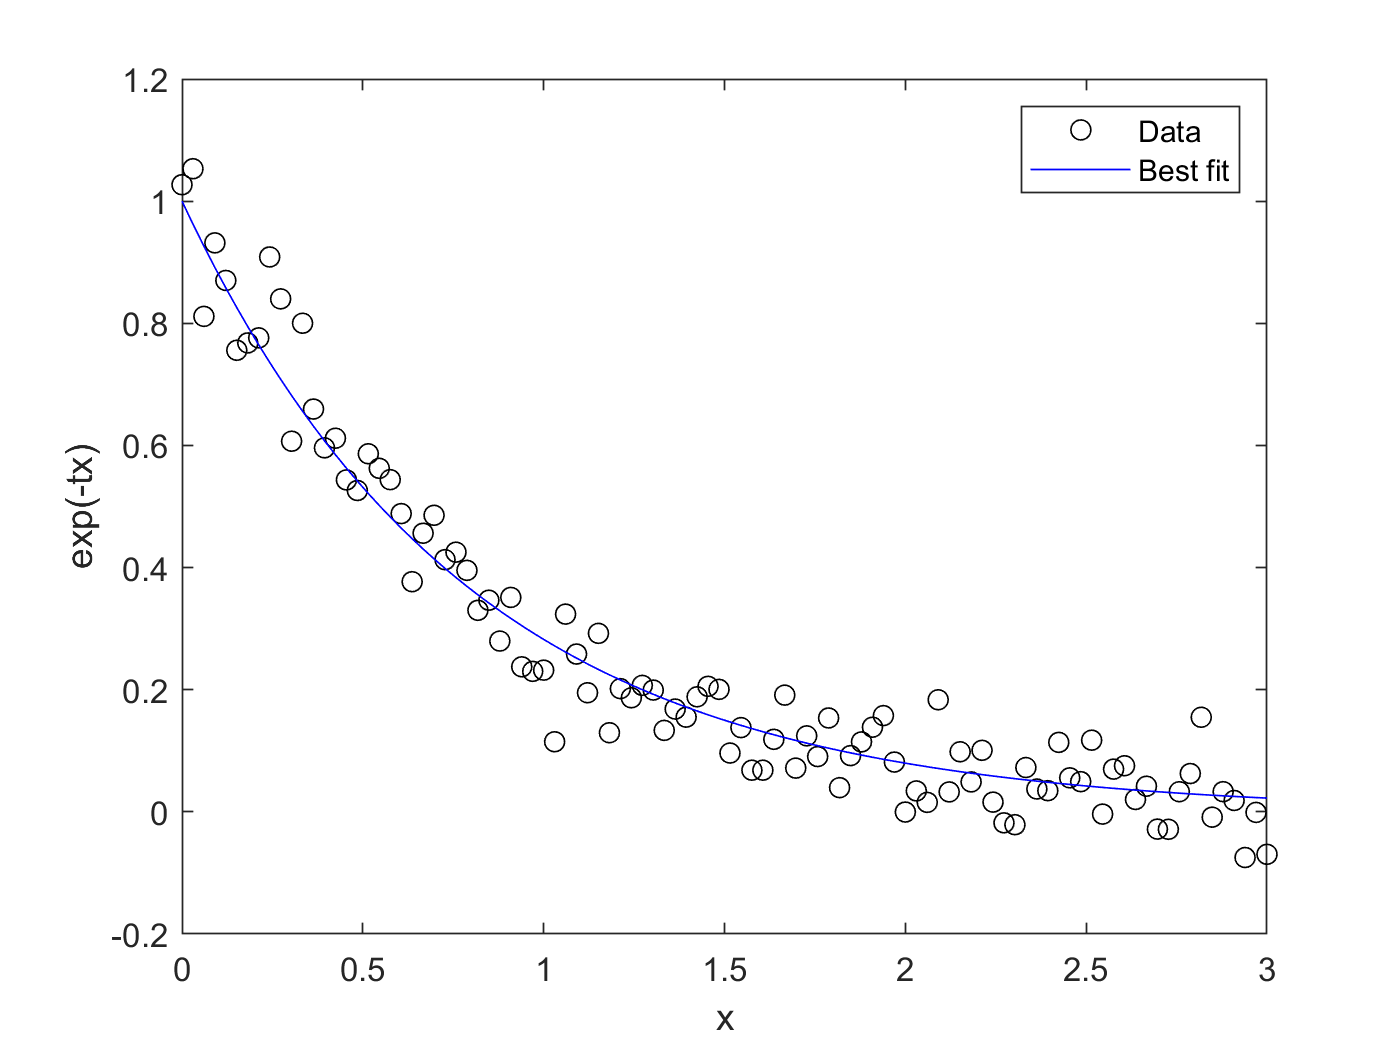

plot(t,y,'ko',t,exp(-x*t),'b-')
legend('Data','Best fit')
xlabel('x')
ylabel('exp(-tx)')